addpath('rawData\data_1\')

load('rawData\data_1\data_1.mat');

%暂时先只处理0.01s。别忘了最终是要处理整个文件的！
seq_sur1=seq_sur(1:(length(seq_sur)/50));
seq_ref1=seq_ref(1:(length(seq_sur)/50));
duration1=0.01;
fs=f_s;

### Task 1

#### Verification of LPF

The LPF filter we will use has this effect:

% [H,w]=freqz(butter(1,9e6/(fs/2),'low'));
% plot(w./(pi/(fs/2)),abs(H))

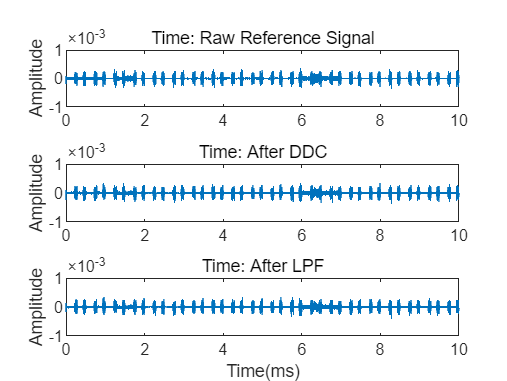

y1rd=sigAfterDDC(seq_ref1,fs);
y1rf=sigAfterLPF(seq_ref1,fs);
plotTimeSig(seq_ref1,fs,1,3,'Time: Raw Reference Signal')
plotTimeSig(y1rd,fs,2,3,'Time: After DDC')
plotTimeSig(y1rf,fs,3,3,'Time: After LPF')

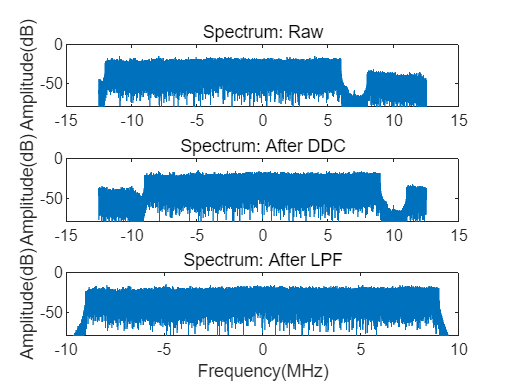


plotSpectrum(seq_ref1,fs,1,3,'Spectrum: Raw')
plotSpectrum(y1rd,fs,2,3,'Spectrum: After DDC')
plotSpectrum(y1rf,fs,3,3,'Spectrum: After LPF')


y1sf=sigAfterLPF(seq_sur1,fs);

### Task 2

It's helpful to know the range of possible time delay and frequency shift. Assume SUSTech has very large football field and the object was running super fast.

From $\tau_{\max } =\frac{2D}{c}$, $f_{D,\max } =v_{\max } \cdot \frac{f_s }{c}$ we get:

disp(['Greatest Possible Time Delay: ',num2str(300/3e8),'=',num2str(300/3e8*fs),'/fs'])

Greatest Possible Time Delay: 1e-06=25/fs


disp(['Greatest Possible Frequency Shift:',num2str(10*2123e6/3e8)])

Greatest Possible Frequency Shift:70.7667


After testing, we found that it's rational to choose smaller ones, such as $\tau \le \frac{6}{f_s },|f_D |\le 40\textrm{Hz}$.

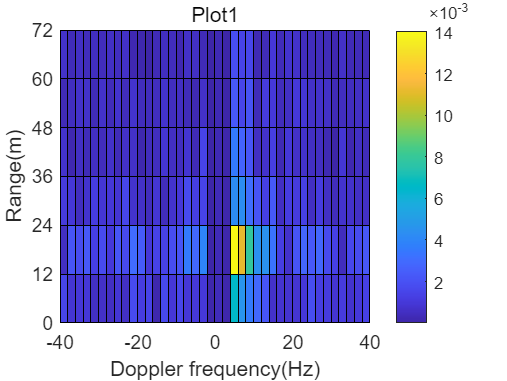

ans = 4.0000e-08

xs1=sigAfterLPF(seq_sur,fs);%现在开始处理0.5s信号！
xr1=sigAfterLPF(seq_ref,fs);
corEst(xs1,xr1,'plot','Plot1')

[tau,fd]=corEst(xs1,xr1,'save','Plot2','thisisfilename.png')

function [tau,fd]=corEst(y_surv,y_ref,varargin)
    
    %可选参数: 是否作图?'plot','save'
    fs=25000000;
    corMat=zeros(7,41);
    Tau=linspace(0,1/fs*6,7);
    Fd=linspace(-40,40,41);
    for i=1:7
        for j=1:41
            corMat(i,j)=corVar(Tau(i),Fd(j),y_surv,y_ref);
        end
    end
    [~,I]=max(corMat(:));%寻找corMat中最大值索引
    [m,n]=ind2sub(size(corMat),I);%索引转为横纵索引

    tau=Tau(m);
    fd=Fd(n);
    numVar=nargin-2;
    %是否作图
    if isempty(varargin)
        return
    elseif strcmp(varargin{1},'plot')||strcmp(varargin{1},'save')
        if numVar<2
            disp('No enough arguments. Check title and/or filename.')
            return
        end
        h=figure;
        pcolor(Fd,Tau.*3e8,corMat);colorbar
        
        xlabel("Doppler frequency(Hz)"),ylabel("Range(m)"),yticks(0:12:72)
        title(varargin{2})

        if strcmp(varargin{1},'save')
            if numVar<3
                disp('Filename not detected!')
                return
            end
            saveas(h,varargin{3},'png')
        end
    else 
        disp('Wrong input.')
    end
end

function Cor=cor(tau,fd,y_surv,y_ref,fs)
    zero_compensation =zeros(1,fix(tau*fs));
    y_surv=[y_surv,zero_compensation];
    y_ref=[zero_compensation,y_ref];

    function y=exp_component(n,fd,fs)
        y=exp((-2i*pi*fd/fs).*linspace(0,n-1,n));
    end
    Cor=abs(sum(y_surv.*conj(y_ref).*exp_component(length(y_surv),fd,fs)));
end

function Cor=corVar(tau,fd,y_surv,y_ref,varargin)
    numVar=nargin-4;
    %可选参数: 采样率、方法

    fs=25000000;
    Type='dot';%这是默认采样率和算法，fft做好后默认要改成fft

    for i=1:numVar%根据可变参数情况设置采样率和算法
        if isnumeric(varargin{i})
            fs=varargin{i};
        elseif ischar(varargin{i})
            Type=varargin{i};
        end
    end

    zero_compensation=zeros(1,fix(tau*fs));%时延后补长信号以对齐
    y_surv=[y_surv,zero_compensation];
    y_ref=[zero_compensation,y_ref];
    
    %以下是侦测方法名选择方法
    if strcmp(Type,'fft')
        %TODO：fft方法
    elseif strcmp(Type,'dot')
        Cor=abs(sum(y_surv.*conj(y_ref).*exp_component(length(y_surv),fd,fs)));
    elseif strcmp(Type,'for')
        Cor=0;
        for k=1:length(y_surv)
            Cor=Cor+y_surv(k)*conj(y_ref(k))*exp(-2j*pi*fd*k/fs);
        end
        Cor=abs(Cor);
    else
        disp('Invalid method name.')
        return;
    end
end

function y=exp_component(n,fd,fs)%dot法要调用的函数
    y=exp((-2i*pi*fd/fs).*linspace(0,n-1,n));
end

#### Basical function

function t=xTime(x,fs)
    t=(0:length(x)-1)./fs;%将x轴用时间表示
end

function plotTimeSig(x,fs,a,n,Title)%n张图中的第a个
    if a==1
        figure
    end
    t=xTime(x,fs);
    subplot(n,1,a),plot(t.*1e3,real(x)),title(Title)
    ylabel("Amplitude"),ylim([-1e-3,1e-3])%注意这里的ylim和PPT不一样
    if a==n
        xlabel("Time(ms)")
    end
end

function plotSpectrum(x,fs,a,n,Title)%n张图中的第a个
    N=length(x);
    H=fftshift(fft(x));
    f=(-N/2:N/2-1)*fs/N;
    if a==1
        figure
    end
    subplot(n,1,a),plot(f./10^6,20*log10(abs(H))),title(Title)
    ylabel('Amplitude(dB)'),ylim([-80,0])
    if a==n
        xlabel('Frequency(MHz)')
    end
end

#### Task 1 function: DDC and filter

function x_moved=sigAfterDDC(x,fs)
    f_ddc=-3e6;
    t=xTime(x,fs);
    x_moved=x.*exp(-1j*2*pi*f_ddc.*t);
end

function x_filtered=sigAfterLPF(x,fs)
    f_ddc=-3e6;
    bandwidth=9e6;
    t=xTime(x,fs);
    x=x.*exp(-1j*2*pi*f_ddc.*t);
    [b,a]=butter(20,bandwidth/(fs/2),'low');
    x_filtered=filter(b,a,x);
end

#### Task 1 function: DDC and filter through spectrum

function [f,H]=AfterLPFSpectrum(x,fs)%已废弃。在时域上filter就可以了
    N=length(x);
    f_ddc=-3e6;
    H=fftshift(fft(x));
    H=circshift(H,-f_ddc/fs*N);
    f=(-N/2:N/2-1)*fs/N;
    [b,a]=butter(4,9e6/(fs/2),'low');[Hf,~]=freqz(b,a,N/2);
    H_all=[flip(Hf);Hf];
    Norm=norm(H);
    H=H.*H_all';
    H=H./norm(H).*Norm;
    subplot(3,1,3),plot(f./10^6,20*log10(abs(H)))
    ylabel('Amplitude(dB)'),ylim([-80,0]),xlabel('Frequency(MHz)')
    title('Spectrum (after LPF)')
end

#### Task 1 function: Cor